# Tarea1 Modelo Lateral Direccional:

clear
close all
load("HinfControllers.mat")
load("modelo_lin.mat")

load("UncertainLinmodel.mat")

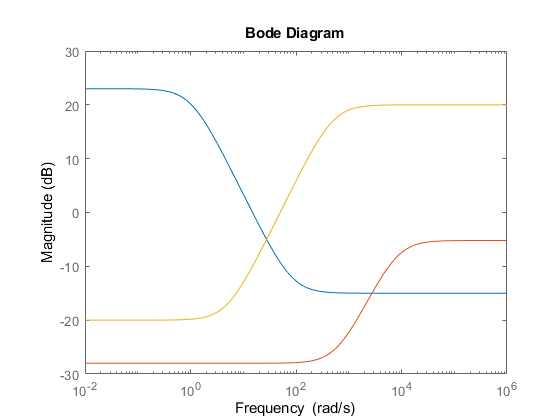

load("modelo_lin.mat")
latmod;
latmod.A(4,4) = 0;
latmod.A(5,4) = 0;

W1 = makeweight(db2mag(23),[15 db2mag(0)],db2mag(-15)); %filtro pasa bajos
W2 = makeweight(db2mag(-28),[600 db2mag(-25)],db2mag(-5.2)); 
W3 = makeweight(db2mag(-20),[50 db2mag(0)],db2mag(20)); %filtro pasa altos

figure(1)
bodemag(W1,W2,W3)


%Peso de las perturbaciones
Wp      = makeweight(1,[10 0.1],0.01);
%Peso Error Ángulo Roll
W1Phi      = W1;
%Peso Error Ángulo Yaw
W1Psi      = W1;%makeweight(db2mag(23),[15 db2mag(0)],db2mag(-15));
%Peso Señal de Control Aileron
W2Aileron      = W2;
%Peso Señal de Control Rudder
W2Rudder      = W2;%makeweight(db2mag(-28),[600 db2mag(-25)],db2mag(-5.2));
%Peso Salida Ángulo Roll
W3Phi      = W3;
%Peso Salida Ángulo Yaw
W3Psi      = W3;%makeweight(db2mag(-10),[50 db2mag(0)],db2mag(25));
%Peso del ruido
Wn      = 0.001;
%Función Delta
%delta = ss([3 0; 0 1.5]);

systemnames     = 'latmod Wp Wn W1Phi W1Psi W2Aileron W2Rudder W3Phi W3Psi';
inputvar        = '[per; n; rPhi; rPsi; uAileron; uRudder]';
outputvar       = '[W1Phi; W1Psi; W2Aileron; W2Rudder; W3Phi; W3Psi; -latmod(4) - Wn + rPhi;-latmod(5) - Wn + rPsi]';
input_to_latmod   = '[-Wp + uAileron; -Wp + uRudder]';
input_to_Wn     = '[n]';
input_to_Wp     = '[per]';
input_to_W1Phi     = '[-latmod(4) - Wn + rPhi]';
input_to_W1Psi     = '[-latmod(5) - Wn + rPsi]';
input_to_W2Phi     = '[uAileron]';
input_to_W2Psi     = '[uRudder]';
input_to_W3Phi     = '[latmod(4)]';
input_to_W3Psi     = '[latmod(5)]';
%input_to_delta     = '[latmod(4); latmod(5)]';

%Planta generalizada
Planta = sysic;

%Diseño controlador Hinf
ncont = 2; 
nmeas = 2; 
[K_LatDir,CL,gamma] = hinfsyn(Planta,nmeas,ncont);

%Función de Lazo abierto
L = latmod*K_LatDir;

%Sistema en Lazo cerrado
Go = feedback(L,eye(2),[1,2],[4,5]);
Go.InputName={'aileron','rudder'}

Go =
 
  A = 
                 v           p
   v        -0.875      0.8751
   p        -2.831      -16.14
   r         1.706      0.5154
   phi           0           1
   psi           0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
   ?             0           0
 
                 r         phi
   v        -16.82       9.791
   p         3.377           0
   r        -2.783           0
   phi     0.05385           0
   psi       1.001           0
   ?             0        -277
   ?             0       128.3
   ?             0       61.39
   ?             0       42.94
   ?             0       27.06
   ?             0       6.933
   ?             0          -4
   ?             0  -8.

%Ancho de banda de los sistemas
BWPhi = bandwidth(Go(4,1))/2/pi

BWPhi =    5.775611649652418


BWPsi = bandwidth(Go(5,2))/2/pi

BWPsi =    4.441777702174222



% Respuesta al paso del sistema
figure()
subplot(2,1,1)
step(Go(4,1));
RespuestaEscalon = stepinfo(Go(4,1))

RespuestaEscalon = struct with fields:
        RiseTime: 0.052518248699018
    SettlingTime: 0.661458275263181
     SettlingMin: 0.875645374337034
     SettlingMax: 1.104435503819126
       Overshoot: 13.623904265568964
      Undershoot: 0
            Peak: 1.104435503819126
        PeakTime: 0.158657305653654


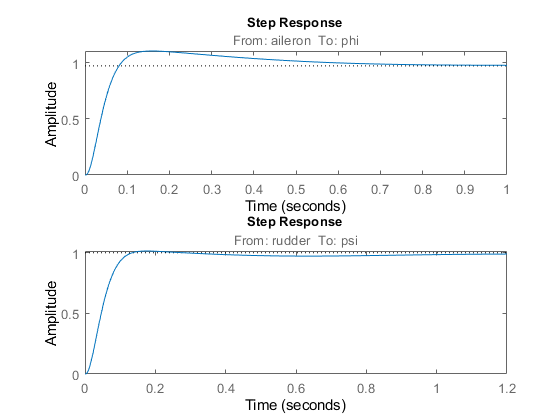

subplot(2,1,2)
step(Go(5,2));

RespuestaEscalon2 = stepinfo(Go(5,2))

RespuestaEscalon2 = struct with fields:
        RiseTime: 0.075494751841915
    SettlingTime: 0.880922332379839
     SettlingMin: 0.903252488235621
     SettlingMax: 1.014688736786932
       Overshoot: 1.468873678693239
      Undershoot: 0
            Peak: 1.014688736786932
        PeakTime: 0.175765115044048


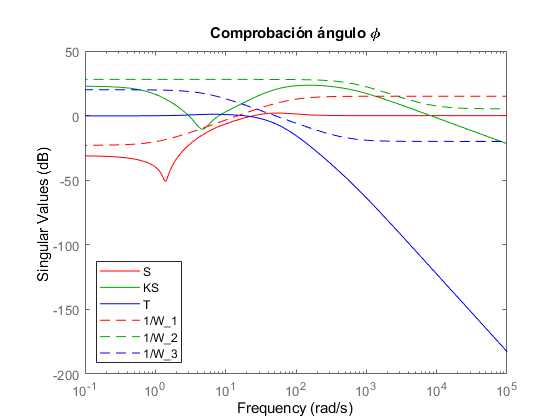


%Función de Sensibilidad Complementaria
T = feedback(L,eye(2),[1,2],[4,5]);

% Función de Sensibilidad
% S = feedback(eye(2),L,[1,2],[1,2]);
S = ones(5,2) - T;

% Función KS
KS = S*K_LatDir;

%Comprobaciones W1
%Phi
figure ()
sigma(S(4,1),'r');
hold on
sigma(KS(4,1),'g');
sigma(T(4,1),'b');
sigma(1/W1Phi,'r--');
sigma(1/W2Aileron,'g--');
sigma(1/W3Phi,'b--');
legend({'S','KS','T','1/W_1','1/W_2','1/W_3'},'Location','southwest')
title('Comprobación ángulo \phi')

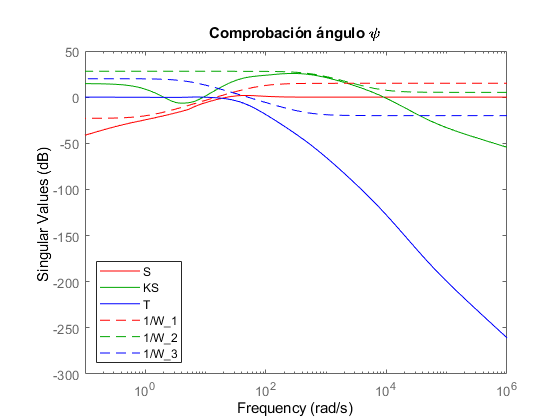


%Psi
figure ()
sigma(S(5,2),'r');
hold on
sigma(KS(5,2),'g');
sigma(T(5,2),'b');
sigma(1/W1Psi,'r--');
sigma(1/W2Rudder,'g--');
sigma(1/W3Psi,'b--');
legend({'S','KS','T','1/W_1','1/W_2','1/W_3'},'Location','southwest')
title('Comprobación ángulo \psi')


%Modelo con incertidumbre
model2 = createUSSmodel(latmod,10);

L = model2*K_LatDir;

%Sistema en Lazo cerrado
Go = feedback(L,eye(2),[1,2],[4,5]);

% Respuesta al paso del sistema

figure()
subplot(2,1,1)
step(Go(4,1));
RespuestaEscalon = stepinfo(Go(4,1))

RespuestaEscalon = struct with fields:
        RiseTime: 0.052518248699018
    SettlingTime: 0.661458275263181
     SettlingMin: 0.875645374337034
     SettlingMax: 1.104435503819126
       Overshoot: 13.623904265568964
      Undershoot: 0
            Peak: 1.104435503819126
        PeakTime: 0.158657305653654


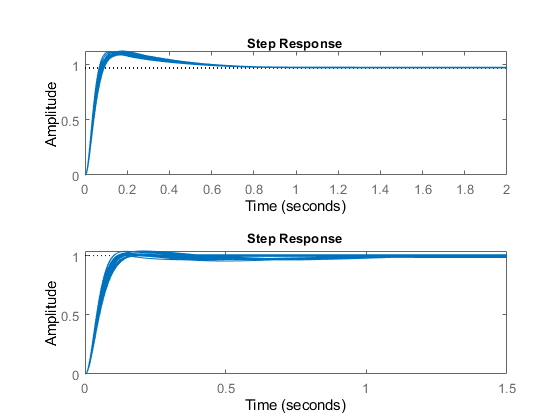

subplot(2,1,2)
step(Go(5,2));

RespuestaEscalon2 = stepinfo(Go(5,2))

RespuestaEscalon2 = struct with fields:
        RiseTime: 0.075494751841915
    SettlingTime: 0.880922332379839
     SettlingMin: 0.903252488235621
     SettlingMax: 1.014688736786932
       Overshoot: 1.468873678693239
      Undershoot: 0
            Peak: 1.014688736786932
        PeakTime: 0.175765115044048




%Función de Sensibilidad Complementaria
T = feedback(L,eye(2),[1,2],[4,5]);

% Función de Sensibilidad
% S = feedback(eye(2),L,[1,2],[1,2]);
S = ones(5,2) - T;

% Función KS
KS = S*K_LatDir;


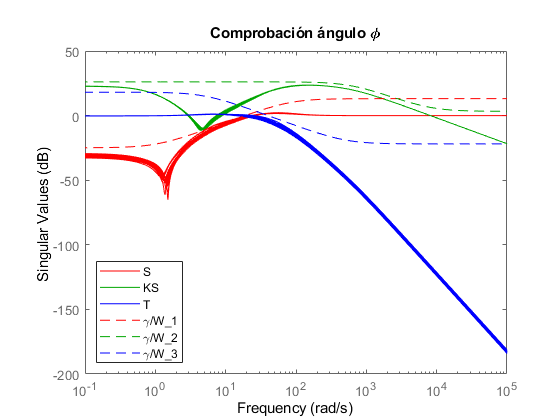


%Comprobaciones W1
%Phi
figure ()
sigma(S(4,1),'r');
hold on
sigma(KS(4,1),'g');
sigma(T(4,1),'b');
sigma(gamma/W1Phi,'r--');
sigma(gamma/W2Aileron,'g--');
sigma(gamma/W3Phi,'b--');
legend({'S','KS','T','\gamma/W_1','\gamma/W_2','\gamma/W_3'},'Location','southwest')
title('Comprobación ángulo \phi')
hold off

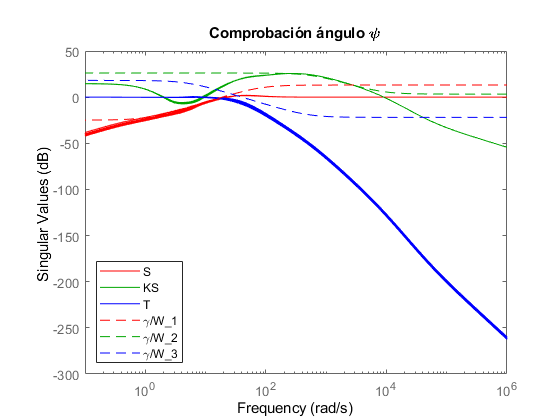


%Psi
figure ()
sigma(S(5,2),'r');
hold on
sigma(KS(5,2),'g');
sigma(T(5,2),'b');
sigma(gamma/W1Psi,'r--');
sigma(gamma/W2Rudder,'g--');
sigma(gamma/W3Psi,'b--');
legend({'S','KS','T','\gamma/W_1','\gamma/W_2','\gamma/W_3'},'Location','southwest')
title('Comprobación ángulo \psi')
hold off